# Example 1: Fitting the parameters to the model using simulated data

The generalized SEIR model inspired by [1] is used to simulate epidemic breakout. Although ref. [1] is a preprint that has not been peer-reviewed, it relies on a fairly standard model that I am using here. 

In [1], there are seven different states

- Susceptibles cases S(t)

- Insusceptibles cases P(t)

- Exposed cases E(t)

- Infectious cases I(t)

- Quarantined cases Q(t)

- Recovered cases R(t)

- Dead cases D(t)

The parameters are as follows:

- alpha: protection rate

- beta: infection rate

- gamma: Inverse of the average latent time

- delta: inverse of the average quarantine time

- lambda0: coefficient used in the time-dependant cure rate

- kappa0: coefficient used in the time-dependant mortality rate

The population is assumed constant, i.e. the births and natural death are not modelled. The cure rate and death rate are here time-dependant but they need some empirical coefficients to tune the time-dependency of these parameters.

The generalized SERI model is as follows:


$$\frac{\mathrm{d}S(t)}{\mathrm{d}t} = -\alpha S(t) -\beta \frac{S(t)I(t)}{N_{pop}}  \\
\frac{\mathrm{d}E(t)}{\mathrm{d}t} = -\gamma E(t) +\beta \frac{S(t)I(t)}{N_{pop}}  \\
\frac{\mathrm{d}I(t)}{\mathrm{d}t} = \gamma E(t) -\delta I(t)  \\
\frac{\mathrm{d}Q(t)}{\mathrm{d}t} = \delta I(t) -\lambda(t)Q(t) - \kappa(t) Q(t)  \\
\frac{\mathrm{d}R(t)}{\mathrm{d}t} = \lambda(t) Q(t) \\
\frac{\mathrm{d}D(t)}{\mathrm{d}t} = \kappa(t) Q(t) \\
\frac{\mathrm{d}P(t)}{\mathrm{d}t} = \alpha S(t) $$


Here, I simply decided to model $\kappa \left(t\right)$ and $\lambda \left(t\right)$  as:


$$\kappa \left(t\right)=0\ldotp 006\;\mathrm{exp}\left(-\kappa_{0\;} t\right)\;$$



$$\lambda \;\left(t\right)=0\ldotp 003\;\left\lbrack 1-\mathrm{exp}\left(-\lambda_0 \;t\right)\right\rbrack$$


The system of ODEs can be re-written in a matrix form:


$$\frac{\mathrm{dY}}{\mathrm{dt}}=A*Y+F$$


where 


$$Y={\left\lbrack S,E,I,Q,R,D,P\right\rbrack }^{\top } \;$$



$$A=\left\lbrack \begin{array}{cccccccc}
-\alpha  & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & -\gamma  & 0 & 0 & 0 & 0 & 0 & 0\\
0 & \gamma  & -\delta  & 0 & 0 & 0 & 0 & 0\\
0 & 0 & \delta  & -\kappa \left(t\right)-\lambda \left(t\right) & 0 & 0 & 0 & 0\\
0 & 0 & 0 & \lambda \left(t\right) & 0 & 0 & 0 & 0\\
0 & 0 & 0 & \kappa \left(t\right) & 0 & 0 & 0 & 0\\
\alpha  & 0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$



$$F=S\left(t\right)\cdot \;I\left(t\right)\cdot \left\lbrack \begin{array}{c}
-\frac{\beta }{N_{\mathrm{pop}} }\\
\frac{\beta }{N_{\mathrm{pop}} }\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


The equation $\frac{\mathrm{dY}}{\mathrm{dt}}=A*Y+F$ is solved using the classic 4th order  Runge-Kutta method.

References

[1] https://arxiv.org/pdf/2002.06563.pdf

## Initialisation

Case of an epidemy outbreak that takes place on 2010-01-01. THe simulation time takes 9 months.

clearvars;close all;clc;

% Time definition
dt = 0.1; % time step
time1 = datetime(2010,01,01,0,0,0):dt:datetime(2010,09,01,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;

## Generate the data

Npop= 60e6; % population (60 milliones)
I0 = 100; % Initial number of infectious
E0 = 0; % Initial number of exposed
R0 = 0; % Initial number of recovereds
D0 = 0; % Initial number of deads
alpha = 0.08; %  protection rate
beta = 1.0; %  infection rate
gamma= 1/5; % inverse of average latent time
delta= 1/40; % inverse of average quarantine time
Lambda0 = 0.05; % cure rate (time dependant)
Kappa0 =  0.02; % mortality rate (time dependant)
[S,E,I,Q,R,D,P] = SEIQRDP(alpha,beta,gamma,delta,Lambda0,Kappa0,Npop,E0,I0,R0,D0,t);

## Fit the data

The fitting is done base on the time histories of the number of infectious, recovered and deads only. The number of exposed,  susceptible, inscuceptible and quarantined is used in the model but not fitted.

guess = [0.05,1,1/5,1/20,0.03,0.01];
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = fit_SEIQRDP(I,R,D,Npop,time1,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          7     1.05095e+14                      4.77e+16
     1         14     1.56781e+13      0.0180475       6.62e+15      
     2         21     2.04426e+12      0.0144764       9.44e+14      
     3         28     1.76631e+11      0.0088443       1.32e+14      
     4         35     5.34483e+09      0.0431778       1.24e+13      
     5         42     1.70518e+08     0.00837114       1.01e+12      
     6         49     3.25586e+06     0.00597493       1.16e+11      
     7         56         2422.26    0.000721862       2.45e+09      
     8         63         1057.29    0.000894137       1.75e+08      
     9         70         1057.29     0.00172167       1.75e+08      
    10         77         925.926    0.000430418       6.49e+07      
    11         84          778.77    0.000860837       1.21e+08      
    12         91         618.61


% Initial conditions
I0 = I(1);
R0 = R(1);
D0 = D(1);

[S1,E1,I1,Q1,R1,D1,P1] =...
    SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,R0,D0,t);

## Comparison beween fitted and generated time histories

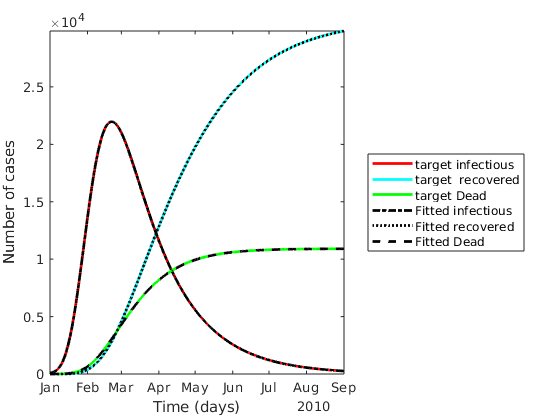

figure
clf;close all;
plot(time1,I,'r',time1,R,'c',time1,D,'g','linewidth',2);
hold on
plot(time1,I1,'k-.',time1,R1,'k:',time1,D1,'k--','linewidth',2);
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('Time (days)')
leg = {'target infectious','target  recovered','target Dead','Fitted infectious','Fitted recovered','Fitted Dead'};
legend(leg{:},'location','eastoutside')
set(gcf,'color','w')
axis tight